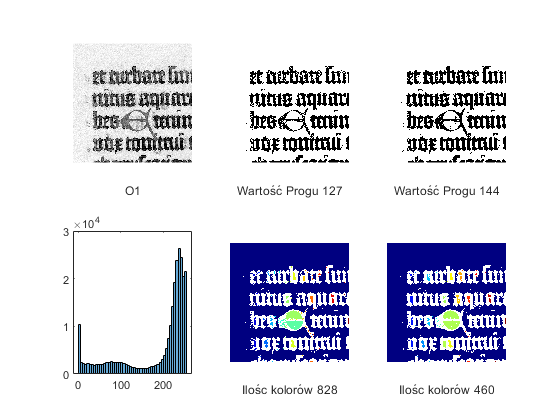

%%ZAD1 
clc; clear all
O1=rgb2gray(imread("1.png"));
O2=rgb2gray(imread("2.png"));
O3=rgb2gray(imread("4.png"));
O4=rgb2gray(imread("5.png"));
%binarka
[O1bin,o1prog]=binarka(O1,127);
[O2bin,o2prog]=binarka(O2,127);
[O3bin,o3prog]=binarka(O3,127);
[O4bin,o4prog]=binarka(O4,127);
%kolor binarka
pseudoO1=bwlabel(O1bin);
pseudoO2=bwlabel(O2bin);
pseudoO3=bwlabel(O3bin);
pseudoO4=bwlabel(O4bin);
rk1=max(unique(pseudoO1))+1;
rk2=max(unique(pseudoO2))+1;
rk3=max(unique(pseudoO3))+1;
rk4=max(unique(pseudoO4))+1;
pseudoO1=label2rgb(pseudoO1);
pseudoO2=label2rgb(pseudoO2);
pseudoO3=label2rgb(pseudoO3);
pseudoO4=label2rgb(pseudoO4);
%otsu 
O1op=graythresh(O1)*255;
O2op=graythresh(O2)*255;
O3op=graythresh(O3)*255;
O4op=graythresh(O4)*255;

O1obin=binarka(O1,O1op);
O2obin=binarka(O2,O2op);
O3obin=binarka(O3,O3op);
O4obin=binarka(O4,O4op);
%kolor otsu
pseudoO1o=bwlabel(O1obin);
pseudoO2o=bwlabel(O2obin);
pseudoO3o=bwlabel(O3obin);
pseudoO4o=bwlabel(O4obin);
sk1=max(unique(pseudoO1o))+1;
sk2=max(unique(pseudoO2o))+1;
sk3=max(unique(pseudoO3o))+1;
sk4=max(unique(pseudoO4o))+1;
pseudoO1o=label2rgb(pseudoO1o);
pseudoO2o=label2rgb(pseudoO2o);
pseudoO3o=label2rgb(pseudoO3o);
pseudoO4o=label2rgb(pseudoO4o);

A=figure();
subplot(2,3,1);
imshow(O1);
xlabel("O1")
subplot(2,3,2);
imshow(O1bin);
xlabel("Wartość Progu "+o1prog)
subplot(2,3,3);
imshow(O1obin)
xlabel("Wartość Progu "+O1op)
subplot(2,3,4);
histogram(O1);
subplot(2,3,5);
imshow(pseudoO1);
xlabel("Ilośc kolorów " +rk1)
subplot(2,3,6);
imshow(pseudoO1o);
xlabel("Ilośc kolorów " +sk1)

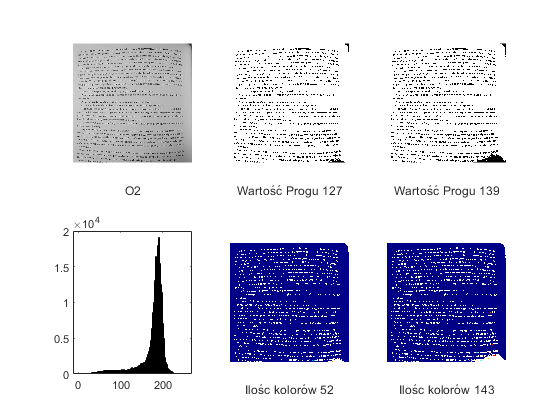


B=figure();
subplot(2,3,1);
imshow(O2);
xlabel("O2")
subplot(2,3,2);
imshow(O2bin);
xlabel("Wartość Progu "+o2prog)
subplot(2,3,3);
imshow(O2obin)
xlabel("Wartość Progu "+O2op)
subplot(2,3,4);
histogram(O2);
subplot(2,3,5);
imshow(pseudoO2);
xlabel("Ilośc kolorów " +rk2)
subplot(2,3,6);
imshow(pseudoO2o);
xlabel("Ilośc kolorów " +sk2)

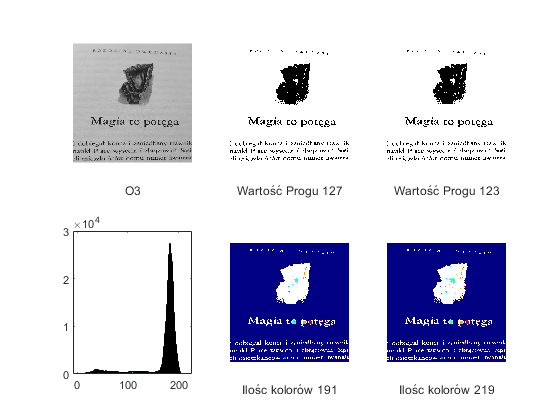


C=figure();
subplot(2,3,1);
imshow(O3);
xlabel("O3")
subplot(2,3,2);
imshow(O3bin);
xlabel("Wartość Progu "+o3prog)
subplot(2,3,3);
imshow(O3obin)
xlabel("Wartość Progu "+O3op)
subplot(2,3,4);
histogram(O3);
subplot(2,3,5);
imshow(pseudoO3);
xlabel("Ilośc kolorów "+rk3)
subplot(2,3,6);
imshow(pseudoO3o);
xlabel("Ilośc kolorów "+sk3)

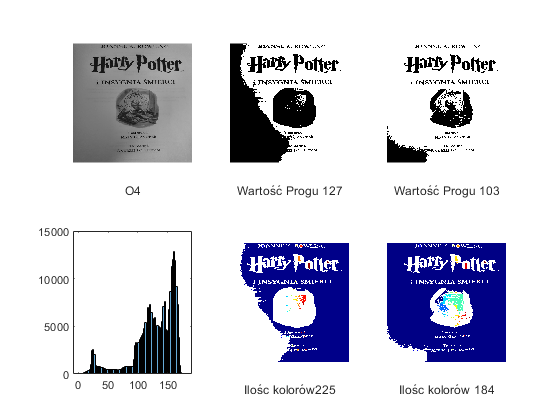


D=figure();
subplot(2,3,1);
imshow(O4);
xlabel("O4")
subplot(2,3,2);
imshow(O4bin);
xlabel("Wartość Progu "+o4prog)
subplot(2,3,3);
imshow(O4obin)
xlabel("Wartość Progu "+O4op)
subplot(2,3,4);
histogram(O4);
subplot(2,3,5);
imshow(pseudoO4);
xlabel("Ilośc kolorów" +rk4)
subplot(2,3,6);
imshow(pseudoO4o);
xlabel("Ilośc kolorów " +sk4)